# Trajectory Reconstruction

clear; clc;

rec3Chicane = [3490, 3900]; 

% Identifed Laps by loop closures to within 1cm

rec1Lap = [4550, 6720];  % 0.19
rec2Lap = [2080, 4060]; 
rec3Lap = [1390, 3420]; 
rec4Lap = [100, 1700];  % 0.24
rec5Lap = [980, 2330; 3585, 5090]; % 0.28
rec6Lap = [65, 1285; 2140, 3500]; % 0.3 m/s
rec7Lap = [65, 1100;2220, 3360]; % 0.35 m/s 



%% Analyse Lap Performance
fig =  figure;
% Load and process data
[timestamps, timedelta, data] = parseDataSet("DataSets/rec3.csv");
dt = mean(timedelta) * 1e-9;  % Convert nanoseconds to seconds

% Configuration parameters
config.start = rec3Lap(1);
config.stop = rec3Lap(2);
config.heading_subsample = 30;
config.path_line_style = '--';
config.heading_scale = 0.7;
config.colors.path = [0, 0.9, 0.7];      
config.colors.heading = [0.1, 0.1, 0.6]; 
config.theta0 = deg2rad(-110);
config.x0 =0;
config.y0=0;

% Calculate trajectory points using dead reckoning
[x, y, theta, linvel, lapstats] = ddmrDeadReconingMap(data, dt, config);
lapstats

lapstats = struct with fields:
      trgt: 0.1900
      mean: -0.1892
    median: -0.1960
      mode: -0.1960
       dev: 0.1057
       var: 0.0112
      time: 40.5937


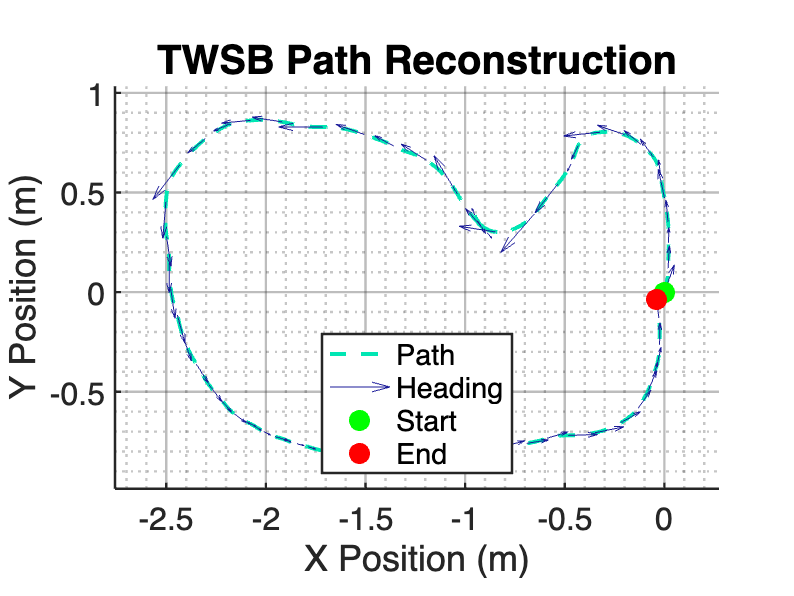

%% Create Static Map Plot (handled outside of the function)
figStatic = figure('Name', 'Static Trajectory Map', 'Color', 'w');
axStatic = axes(figStatic);
hold(axStatic, 'on');

% Plot trajectory and markers on the static map
plotTrajectory(axStatic, x, y, theta, linvel, config);
plotStartEndMarkers(axStatic, x, y);
% Configure axes appearance
set(axStatic, 'FontSize', 16, 'XGrid', 'on', 'YGrid', 'on', 'GridAlpha', 0.3, 'LineWidth', 1.2);
grid minor;
xlabel(axStatic, 'X Position (m)', 'FontSize', 18);
ylabel(axStatic, 'Y Position (m)', 'FontSize', 18);
title(axStatic, 'TWSB Path Reconstruction', 'FontSize', 20);
axis(axStatic, 'equal');
    x_range = max(x) - min(x);
    y_range = max(y) - min(y);
    x_margin = 0.1 * x_range;
    y_margin = 0.1 * y_range;
    xlim(axStatic, [min(x)-x_margin, max(x)+x_margin]);
    ylim(axStatic, [min(y)-y_margin, max(y)+y_margin]);
hold(axStatic, 'off');     legend('Location','south');


exportgraphics(fig, '../Docs/Y3Report/Images/Graphs/DeadReckoningTrackMap.pdf')


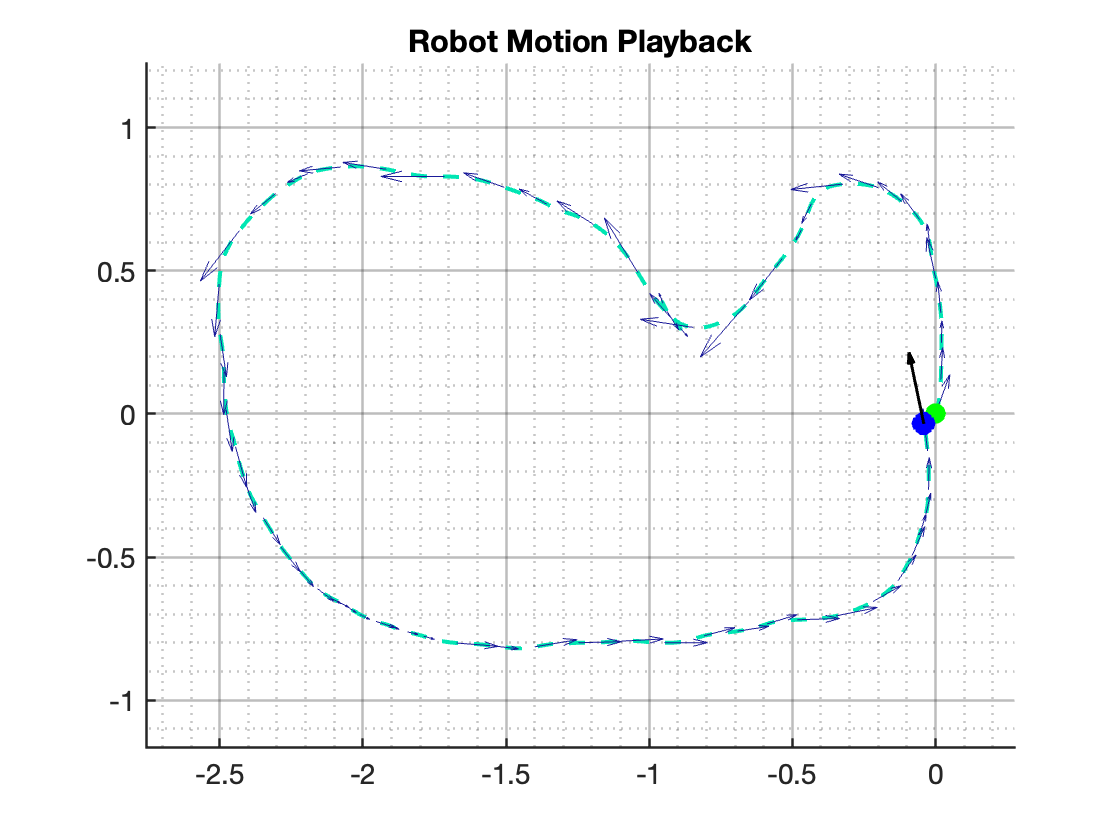


%% Visualize Trajectory Animation with Fixed Axes Borders
animateTrajectory(x, y, theta, linvel, dt, config, ...
    'PlaybackSpeed', 1, ...
    'PathStyle', '--', ...
    'Title', 'Robot Motion Playback');

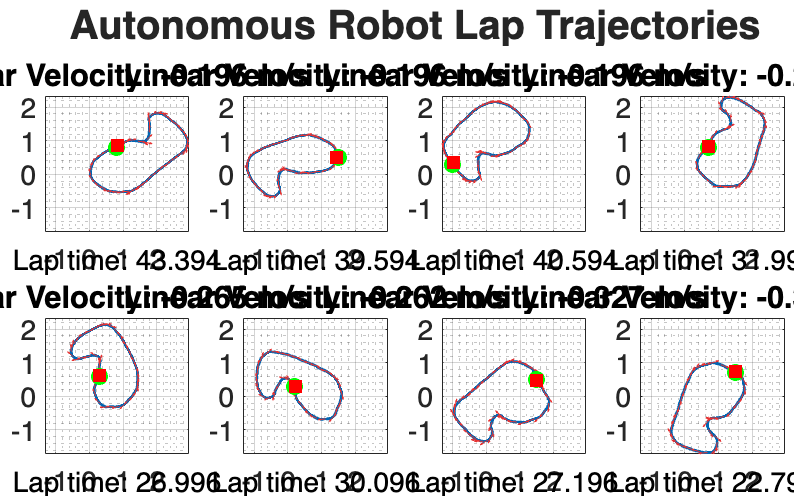

%% Analyze and Plot All Laps in Tiled Layout
fig = figure('Color', 'w', 'Units', 'normalized', ...
    'Position', [0.1 0.1 0.8 0.8], 'Name', 'Lap Analysis Poster');
mainLayout = tiledlayout(fig, 2, 4, 'TileSpacing', 'tight', 'Padding', 'tight');

% Configuration parameters
config = struct();
config.heading_subsample = 30;
config.path_line_style = '-';
config.heading_scale = 0.5;
config.colors.path = [0, 0.4, 0.7];
config.colors.heading = [0.9, 0.2, 0.2];

% Identified Laps (Manually Defined)
rec1Lap = [4550, 6720];  
rec2Lap = [2080, 4060]; 
rec3Lap = [1390, 3420]; 
rec4Lap = [100, 1700];  
rec5Lap = [980, 2330; 3585, 5090]; 
rec6Lap = [ 2140, 3500]; 
rec7Lap = [ 2220, 3360]; 

% initial conditions for each lap (total 10 laps)
initialTheta = deg2rad([20; -80; 110; 35; 60; 80;  -70; -55]);
initialX = [0.8; 1.5; -1.0; 0.7; 0.3; 0.2;  1.5;  1.5];
initialY = [0.8; 0.5; 0.3; 0.8; 0.6; 0.3;  0.5;  0.7];

lapCounter = 0;  % counter for laps across all datasets

% Initialize global limits and store axes handles
globalXMin = inf; globalXMax = -inf;
globalYMin = inf; globalYMax = -inf;
axesHandles = {};

% Get lap variables and process each dataset's laps
lapVars = who('rec*Lap');
for varIdx = 1:numel(lapVars)
    varName = lapVars{varIdx};
    lapIntervals = eval(varName);
    datasetNum = sscanf(varName, 'rec%dLap');
    
    % Load dataset once per recording
    dataPath = sprintf('DataSets/rec%d.csv', datasetNum);
    [~, timedelta, data] = parseDataSet(dataPath);
    dt = mean(timedelta) * 1e-9;
    
    % Process each lap interval for the current dataset
    for lapIdx = 1:size(lapIntervals, 1)
        lapCounter = lapCounter + 1; % increment for each lap
        
        % Configure lap parameters
        config.start = lapIntervals(lapIdx, 1);
        config.stop = lapIntervals(lapIdx, 2);
        config.theta0 = initialTheta(lapCounter);  % assign unique initial condition
        config.x0 = initialX(lapCounter);
        config.y0 = initialY(lapCounter);
        
        % Calculate trajectory using dead reckoning and capture stats
        [x, y, theta, linvel, stats] = ddmrDeadReconingMap(data, dt, config);
        
        % Update global axis limits
        globalXMin = min(globalXMin, min(x));
        globalXMax = max(globalXMax, max(x));
        globalYMin = min(globalYMin, min(y));
        globalYMax = max(globalYMax, max(y));
        
        % Create new tile for this lap's trajectory
        ax = nexttile(mainLayout);
        axesHandles{end+1} = ax;
        hold(ax, 'on');
        
        % Plot trajectory and heading arrows
        plot(ax, x, y, config.path_line_style, 'LineWidth', 1.5, ...
            'Color', config.colors.path);
        idx = 1:config.heading_subsample:length(x);
        quiver(ax, x(idx), y(idx), cos(theta(idx)), sin(theta(idx)), ...
            config.heading_scale, 'Color', config.colors.heading);
        
        % Mark start and end points
        plot(ax, x(1), y(1), 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 8);
        plot(ax, x(end), y(end), 'rs', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
        
        % Place the median speed as the title (at the top)
        title(ax, sprintf('Linear Velocity: %.3f m/s', stats.median), ...
            'FontSize', 18, 'FontWeight', 'bold');
        
        % Place lap time and variance below the tile using normalized coordinates
        text(ax, 0.5,-0.2, sprintf('Lap time: %.3f', stats.time), ...
             'Units', 'normalized', 'FontSize', 14, 'HorizontalAlignment', 'center');
        
        % Additional formatting for the tile
        set(ax, 'FontSize', 14, 'XGrid', 'on', 'YGrid', 'on', 'GridAlpha', 0.2, 'Box', 'on');
        axis(ax, 'equal'); grid minor;
    end
end

% Add margins to the global limits
xRange = globalXMax - globalXMin;
yRange = globalYMax - globalYMin;
xMargin = 0.01 * xRange;
yMargin = 0.01 * yRange;
xLimits = [globalXMin - xMargin, globalXMax + xMargin];
yLimits = [globalYMin - yMargin, globalYMax + yMargin];

% Apply the same axis limits to all tiles
for k = 1:length(axesHandles)
    set(axesHandles{k}, 'XLim', xLimits, 'YLim', yLimits);
end

% Global title and axis labels for the tiled layout
sgtitle(mainLayout, 'Autonomous Robot Lap Trajectories', 'FontSize', 20, 'FontWeight', 'bold');


exportgraphics(fig,'../Docs/Y3Report/DesingImg/Laps.pdf'); 

Error using exportgraphics
The value of 'destination' is invalid. Unable to create output file '../Docs/Y3Report/DesingImg/Laps.pdf', No such file or directory.


%% Utility Functions

function [x, y, theta, linvel, stats] = ddmrDeadReconingMap(data, dt, config)
    % Extract linear and angular velocities from the data
    linvel = -data(config.start:config.stop, 15);
    angvel = -data(config.start:config.stop, 18) * 2 * pi;  % Convert to rad/s
    stats.trgt = data(1, 16);
    stats.mean = mean(linvel);
    stats.median = median(linvel);
    stats.mode = mode(linvel);
    stats.dev = std(linvel);
    stats.var = var(linvel);
    stats.time = (config.stop - config.start) * dt;

    n = length(linvel);
    x = zeros(n, 1);
    y = zeros(n, 1);
    theta = zeros(n, 1);
    theta(1) = config.theta0;
    x(1) = config.x0;
    y(1) = config.y0;
    
    % Forward Euler integration for dead reckoning kinematics
    for i = 2:n
        theta(i) = theta(i-1) + angvel(i-1) * dt;
        x(i) = x(i-1) + linvel(i-1) * cos(theta(i-1)) * dt;
        y(i) = y(i-1) + linvel(i-1) * sin(theta(i-1)) * dt;
    end
end

function plotTrajectory(ax, x, y, theta, linvel, config)
    % Plot the path trajectory
    plot(ax, x, y, config.path_line_style, 'LineWidth', 2, ...
         'Color', config.colors.path, 'DisplayName', 'Path');
    
    % Plot heading arrows at subsampled intervals
    idx = 1:config.heading_subsample:length(x);
    quiver(ax, x(idx), y(idx), cos(theta(idx)) .* linvel(idx), ...
           sin(theta(idx)) .* linvel(idx), config.heading_scale, ...
           'Color', config.colors.heading, 'DisplayName', 'Heading');
end

function plotStartEndMarkers(ax, x, y)
    % Plot the start marker
    plot(ax, x(1), y(1), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'g', ...
         'Color', 'g', 'DisplayName', 'Start');
    
    % Plot the end marker
    plot(ax, x(end), y(end), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'r', ...
         'Color', 'r', 'DisplayName', 'End');
    
end

function animateTrajectory(x, y, theta, linvel, dt, config, varargin)
    % Parse inputs for the animation
    p = inputParser;
    addRequired(p, 'x');
    addRequired(p, 'y');
    addRequired(p, 'theta');
    addRequired(p, 'linvel');
    addRequired(p, 'dt');
    addRequired(p, 'config');
    addParameter(p, 'PlaybackSpeed', 1, @isnumeric);
    addParameter(p, 'FigureVisible', 'on', @ischar);
    addParameter(p, 'PathStyle', '-.', @ischar);
    addParameter(p, 'Title', 'Robot Trajectory Animation', @ischar);
    parse(p, x, y, theta, linvel, dt, config, varargin{:});
    
    % Update configuration for path style if needed
    config.plotStyle = p.Results.PathStyle;
    frameDelay = dt / p.Results.PlaybackSpeed;
    
    % Create figure for animation
    figAnim = figure('Visible', p.Results.FigureVisible, 'Color', 'w');
    axAnim = axes(figAnim);
    hold(axAnim, 'on');
    
    % Plot static trajectory elements on the animation figure
    plotTrajectory(axAnim, x, y, theta, linvel, config);
    plotStartEndMarkers(axAnim, x, y);
    
    % Set fixed axis limits with a 10% margin to prevent dynamic resizing
    x_range = max(x) - min(x);
    y_range = max(y) - min(y);
    x_margin = 0.1 * x_range;
    y_margin = 0.1 * y_range;
    xlim(axAnim, [min(x)-x_margin, max(x)+x_margin]);
    ylim(axAnim, [min(y)-y_margin, max(y)+y_margin]);
    axis(axAnim, 'equal');
    axis(axAnim, 'manual');  % Lock the axis limits
    
    % Initialize animated plot elements (robot marker and heading arrow)
    h_robot = plot(axAnim, x(1), y(1), 'bo', 'MarkerSize', 10, ...
                   'MarkerFaceColor', 'b', 'LineWidth', 2, 'DisplayName', 'Current Position');
    h_arrow = quiver(axAnim, x(1), y(1), cos(theta(1))*linvel(1), sin(theta(1))*linvel(1), ...
                    'AutoScale', 'off', 'Color', 'k', 'LineWidth', 1.5, ...
                    'MaxHeadSize', 0.5, 'DisplayName', 'Current Heading');
    
    % Configure axes appearance and title
    title(axAnim, p.Results.Title, 'FontSize', 20); grid minor;
    set(axAnim, 'FontSize', 14, 'XGrid', 'on', 'YGrid', 'on', 'GridAlpha', 0.3, 'LineWidth', 1.2);
    
    % Animation loop: update the robot's position and heading arrow
    for i = 1:length(x)
        set(h_robot, 'XData', x(i), 'YData', y(i));
        set(h_arrow, 'XData', x(i), 'YData', y(i), ...
            'UData', cos(theta(i)) * linvel(i), 'VData', sin(theta(i)) * linvel(i));
        drawnow;
        pause(frameDelay);
    end
    hold(axAnim, 'off');
end
